# 源信号

## 载波

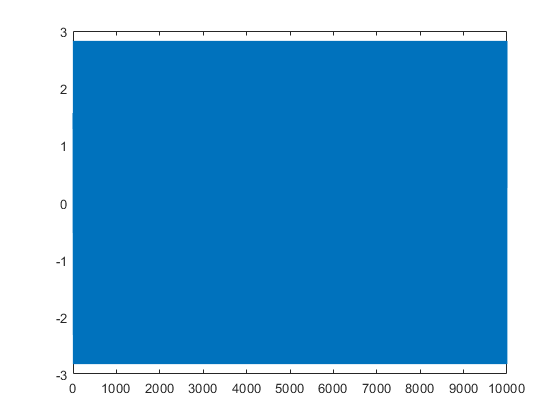

clear
f_source = 100;
fs = f_source * 10;
A_1 = 2;
E = 0 ;
%采样点数 10s
N = 10 * fs;
n = 0 : N-1;
%时间序列
% global t;
t = n / fs ;

y_source_i = A_1 * sin(2 * pi * f_source * t) + E;
y_source_q = A_1 * cos(2 * pi * f_source * t) + E;
y_source = y_source_i + y_source_q * 1i;

y_an = angle(y_source);
figure;
plot(y_an);

## 延时

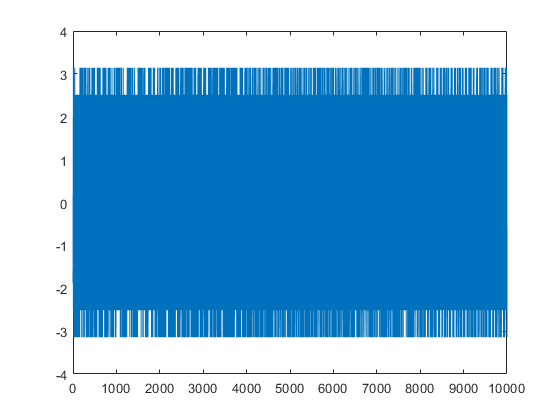


A_2 = 1.5;
t_x = (n + 7) / fs ;
x_source_i = A_2 * cos(2 * pi * f_source * t_x) + E;
x_source_q = A_2 * sin(2 * pi * f_source * t_x) + E;
x_source = x_source_i + x_source_q * 1i;
x_an = angle(x_source);
figure;
plot(x_an);

## tag

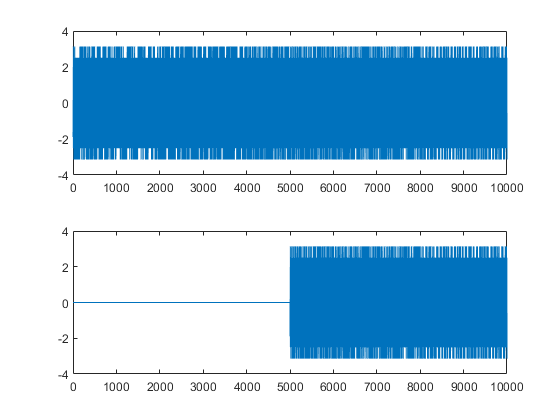



x_s = [zeros(1, length(x_source)/2) x_source(1, 1 + length(x_source)/2 : end) ];
x_s_an = angle(x_s);

figure
subplot(2,1,1);
plot(x_an);
subplot(2,1,2);
plot(x_s_an);

## 加和

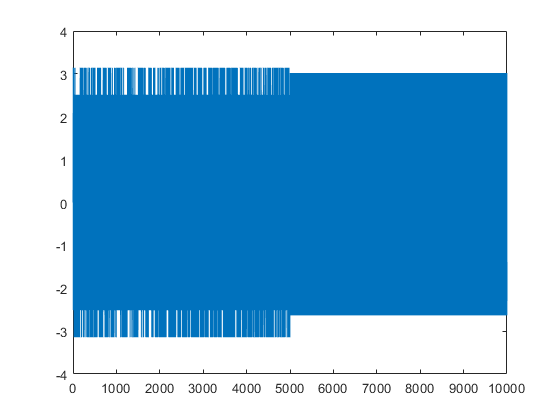


x_y = y_source + x_s;
xy_an = angle(x_y);

figure
plot(xy_an);

## 取点


po = 3001;
theta_1 = y_an(1, po)

theta_1 = -1.0190e-13

theta_2 = x_s_an(1, po)

theta_2 = 0

theta_3 = xy_an(1, po)

theta_3 = -1.0190e-13

sin_2 = sin(theta_2)

sin_2 = 0


v_1 = y_source(1, po)

v_1 = 2.0000 - 0.0000i

v_2 = x_s(1, po)

v_2 = 0

v_3 = x_y(1, po)

v_3 = 2.0000 - 0.0000i



B_1 = 1/tan(theta_3);
B_2 = A_1 * (sin(theta_1) - tan(theta_3) * cos(theta_1)) / (A_2 * tan(theta_3));

syms x
f=(B_1 ^ 2 + 1) *  x^2 + 2 * B_1 * B_2 * x + B_2 ^ 2 - 1

$$f = 96304642164981073241440256\,x^{2}-1$$

result=solve(f==0,x)

$$result = \left(\begin{array}{c} -\frac{\sqrt{5605667955532034}}{734746110267494760448}\\ \frac{\sqrt{5605667955532034}}{734746110267494760448} \end{array}\right)$$


sin_theta = double(result)

sin_theta = 	1.0e+-12 *

   -0.1019
    0.1019


arsin = double(asin(result))

arsin = 	1.0e+-12 *

   -0.1019
    0.1019


po = 3002;
theta_1 = y_an(1, po)

theta_1 = 0.6283

theta_2 = x_s_an(1, po)

theta_2 = 0

theta_3 = xy_an(1, po)

theta_3 = 0.6283

sin_2 = sin(theta_2)

sin_2 = 0


v_1 = y_source(1, po)

v_1 = 1.6180 + 1.1756i

v_2 = x_s(1, po)

v_2 = 0

v_3 = x_y(1, po)

v_3 = 1.6180 + 1.1756i



B_1 = 1/tan(theta_3);
B_2 = A_1 * (sin(theta_1) - tan(theta_3) * cos(theta_1)) / (A_2 * tan(theta_3));

syms x
f=(B_1 ^ 2 + 1) *  x^2 + 2 * B_1 * B_2 * x + B_2 ^ 2 - 1

$$f = \frac{3258835304710701\,x^{2}}{1125899906842624}-1$$

result=solve(f==0,x)

$$result = \left(\begin{array}{c} -\frac{33554432\,\sqrt{3258835304710701}}{3258835304710701}\\ \frac{33554432\,\sqrt{3258835304710701}}{3258835304710701} \end{array}\right)$$


sin_theta = double(result)

sin_theta =    -0.5878
    0.5878


arsin = double(asin(result))

arsin =    -0.6283
    0.6283


po = 3003;
theta_1 = y_an(1, po)

theta_1 = 1.2566

theta_2 = x_s_an(1, po)

theta_2 = 0

theta_3 = xy_an(1, po)

theta_3 = 1.2566

sin_2 = sin(theta_2)

sin_2 = 0


v_1 = y_source(1, po)

v_1 = 0.6180 + 1.9021i

v_2 = x_s(1, po)

v_2 = 0

v_3 = x_y(1, po)

v_3 = 0.6180 + 1.9021i



B_1 = 1/tan(theta_3);
B_2 = A_1 * (sin(theta_1) - tan(theta_3) * cos(theta_1)) / (A_2 * tan(theta_3));

syms x
f=(B_1 ^ 2 + 1) *  x^2 + 2 * B_1 * B_2 * x + B_2 ^ 2 - 1

$$f = \frac{2489528645322111\,x^{2}}{2251799813685248}-1$$

result=solve(f==0,x)

$$result = \left(\begin{array}{c} -\frac{33554432\,\sqrt{553228587849358}}{829842881774037}\\ \frac{33554432\,\sqrt{553228587849358}}{829842881774037} \end{array}\right)$$


sin_theta = double(result)

sin_theta =    -0.9511
    0.9511


arsin = double(asin(result))

arsin =    -1.2566
    1.2566
